# Train a Q-Learning Agent for the Dice Game

## Define the environment

Discrete states and actions. States are the target values 0 - 20. Actions are the choice of die (1-5).

obsInfo = rlFiniteSetSpec(0:20);
actInfo = rlFiniteSetSpec(1:5);

slEnv = rlSimulinkEnv("targetDice","targetDice/RL die chooser",obsInfo,actInfo);
slEnv.ResetFcn = @randomizeseed;

## Define the agent

Create a Q-table representation.

T = rlTable(obsInfo,actInfo);
opts = rlRepresentationOptions("LearnRate",0.005,"GradientThreshold",10);
QT = rlQValueRepresentation(T,obsInfo,actInfo,opts);

Create a Q-learning agent. Use $\gamma$= 1 (all rewards equally weighted).

opts = rlQAgentOptions("DiscountFactor",1);
agent = rlQAgent(QT,opts);

## Train the agent

Check to train agent from scratch.

dotraining = true;

Train agent or load pretrained agent from file.

Training target is an average episode reward of -3. This can happen by luck on the first episode. If so, rerun to try training again.

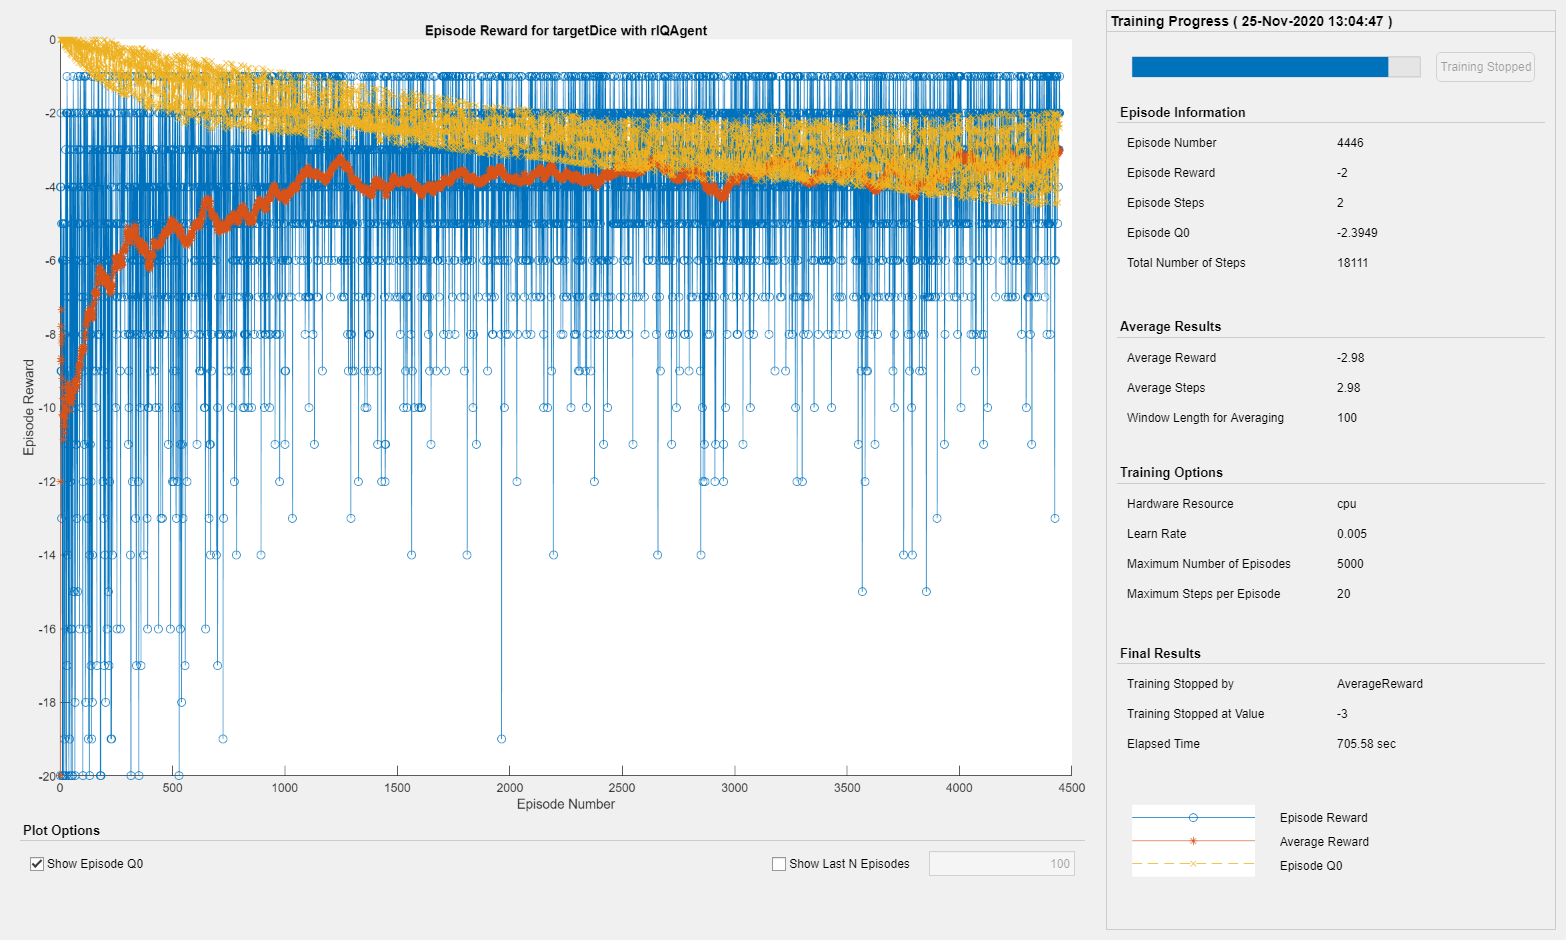

info = struct with fields:
       EpisodeIndex: [4446×1 double]
      EpisodeReward: [4446×1 double]
       EpisodeSteps: [4446×1 double]
      AverageReward: [4446×1 double]
       AverageSteps: [4446×1 double]
    TotalAgentSteps: [4446×1 double]
        Information: [1×1 struct]
          EpisodeQ0: [4446×1 double]
     SimulationInfo: [4446×1 Simulink.SimulationOutput]

if dotraining
    opts = rlTrainingOptions("MaxStepsPerEpisode",20, ...
        "ScoreAveragingWindowLength",100, ...
        "MaxEpisodes",5000, ...
        "StopTrainingCriteria","AverageReward", ...
        "StopTrainingValue",-3);
    info = train(agent,slEnv,opts)
else
    load trainedQ
    agent = partlytrained;
end

## Visualize the trained agent's policy

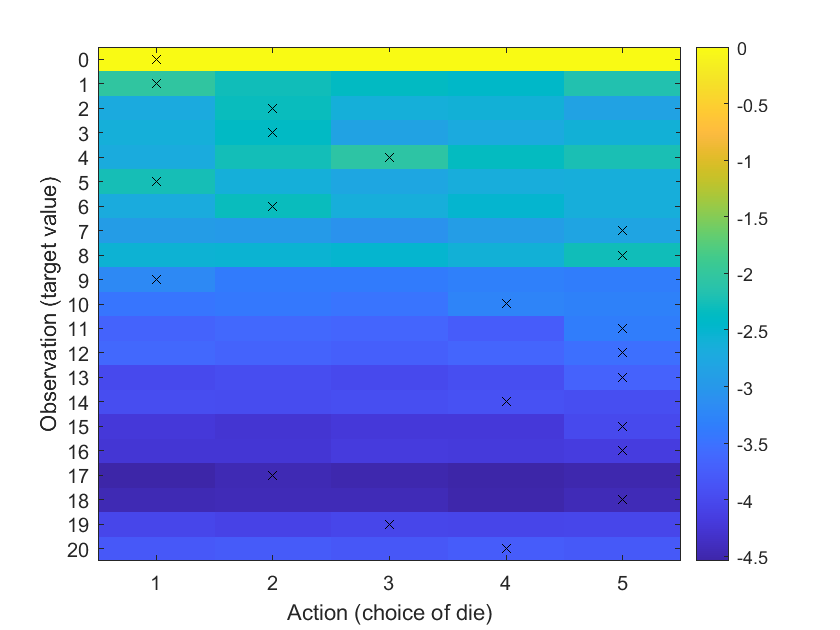

trainedcritic = getCritic(agent);
visualizeQ(trainedcritic)

## Evaluate the agent

Run multiple simulations.

simout = sim(agent,slEnv,rlSimulationOptions("MaxSteps",20,"NumSimulations",100))

simout = 100×1 struct array with fields:
    Observation
    Action
    Reward
    IsDone
    SimulationInfo

Extract the reward/number of steps. Visualize the distribution.

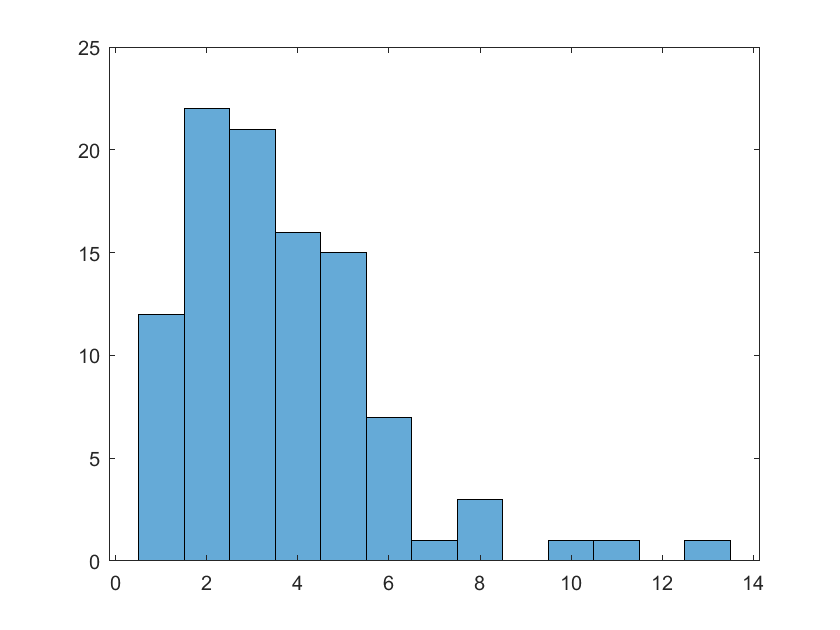

steps = arrayfun(@(x) -sum(x.Reward.Data),simout);
histogram(steps)

meansteps = mean(steps)

meansteps = 3.6500

medsteps = median(steps)

medsteps = 3

### Local functions

Randomize the random number seed in the Simulink model.

function simin = randomizeseed(simin)
simin = setVariable(simin,"seed",randi(1e5),"Workspace","targetDice");
end

Visualize the Q-table representation of an agent.

function visualizeQ(critic)
% Get possible observations and actions
o = critic.ObservationInfo.Elements;
a = critic.ActionInfo.Elements;
no = numel(o);
na = numel(a);
% Get Q value for each obs/action
Q = zeros(no,na);
for k = 1:na
    for j = 1:no
        Q(j,k) = getValue(critic,o(j),a(k));
    end
end
% Visualize result
imagesc(Q)
colorbar
xticks(1:na)
xticklabels(a)
yticks(1:no)
yticklabels(o)
xlabel("Action (choice of die)")
ylabel("Observation (target value)")
% Add policy to the plot
[~,idx] = max(Q,[],2);
hold on
plot(idx,1:no,"kx")
hold off
end